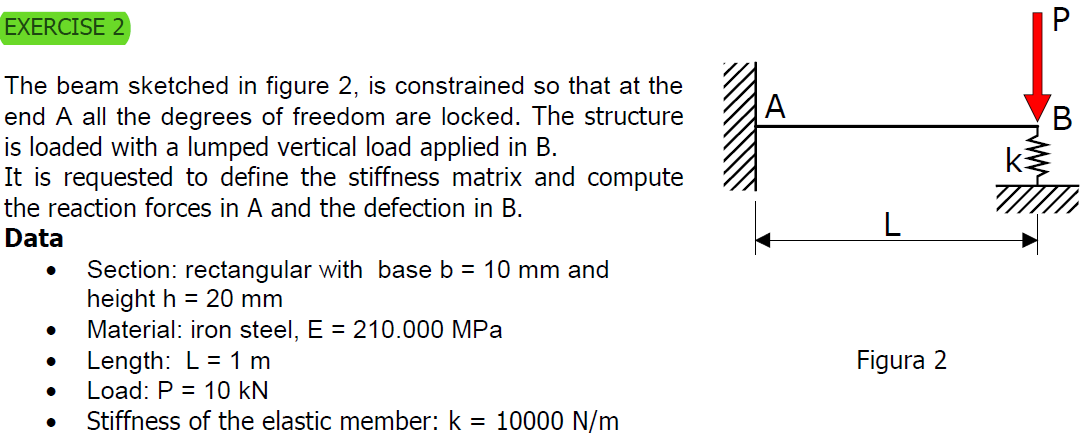

syms b h I E l P k Fs Ma Fa yb K

% b=10
% h=20
% I=b*h^3/12*10^-12

% E=210*10^9
% l=1
% P=10*10^3
% k=10*10^3



yb=P*l^3/(3*E*I+k*l^3);
yb=simplify(yb)

$$yb = \frac{P\,l^{3}}{k\,l^{3}+3\,\text{E}\,\text{I}}$$

Fs=k*yb

$$Fs = \frac{P\,k\,l^{3}}{k\,l^{3}+3\,\text{E}\,\text{I}}$$


phib=-(0.5*l^2*(Fs-P))/(E*I);
phib=simplify(phib)

$$phib = \frac{3\,P\,l^{2}}{2\,k\,l^{3}+6\,\text{E}\,\text{I}}$$




K =(E*I/l^3)*[     12 6*l -12 6*l;
                 6*l 4*l^2 6*l 2*l^2;
                -12 -6*l 12 -6*l;
                6*l 2*l^2 -6*l 4*l^2;];

K

$$K = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1} & -\sigma_{2} & \sigma_{1}\\ \sigma_{1} & \frac{4\,\text{E}\,\text{I}}{l} & \sigma_{1} & \frac{2\,\text{E}\,\text{I}}{l}\\ -\sigma_{2} & -\sigma_{1} & \sigma_{2} & -\sigma_{1}\\ \sigma_{1} & \frac{2\,\text{E}\,\text{I}}{l} & -\sigma_{1} & \frac{4\,\text{E}\,\text{I}}{l} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{6\,\text{E}\,\text{I}}{l^{2}}\\ \sigma_{2}=\frac{12\,\text{E}\,\text{I}}{l^{3}} \end{array}$$

Fa=K(1,3)*yb+K(1,4)*phib

$$Fa = \frac{18\,\text{E}\,\text{I}\,P}{2\,k\,l^{3}+6\,\text{E}\,\text{I}}-\frac{12\,\text{E}\,\text{I}\,P}{k\,l^{3}+3\,\text{E}\,\text{I}}$$

Ma=K(2,3)*yb+K(2,4)*phib

$$Ma = \frac{6\,\text{E}\,\text{I}\,P\,l}{k\,l^{3}+3\,\text{E}\,\text{I}}+\frac{6\,\text{E}\,\text{I}\,P\,l}{2\,k\,l^{3}+6\,\text{E}\,\text{I}}$$

Fb=K(3,3)*yb+K(3,4)*phib

$$Fb = \frac{12\,\text{E}\,\text{I}\,P}{k\,l^{3}+3\,\text{E}\,\text{I}}-\frac{18\,\text{E}\,\text{I}\,P}{2\,k\,l^{3}+6\,\text{E}\,\text{I}}$$

Mb=0

Mb = 0


phib=Mb-K(4,3)*yb/K(4,4)

$$phib = \frac{3\,P\,l^{2}}{2\,\left(k\,l^{3}+3\,\text{E}\,\text{I}\right)}$$

rad2deg(phib)

$$ans = \frac{270\,P\,l^{2}}{\pi \,\left(k\,l^{3}+3\,\text{E}\,\text{I}\right)}$$